Loading Images

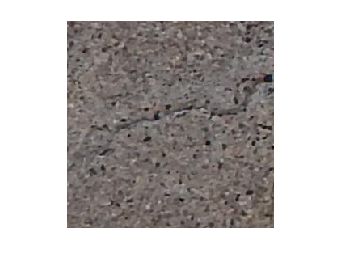

im1=imread('Crack Images\im3.jpg');
imshow(im1)

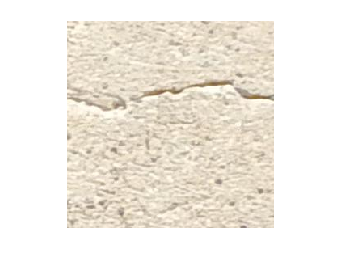

im2=imread('Crack Images\im2.jpg');
imshow(im2)

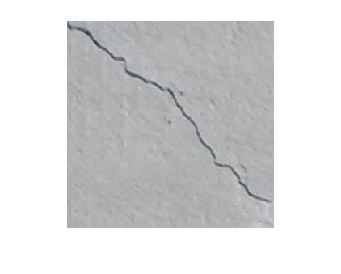

im3=imread('Crack Images\im6.jpg');
imshow(im3)

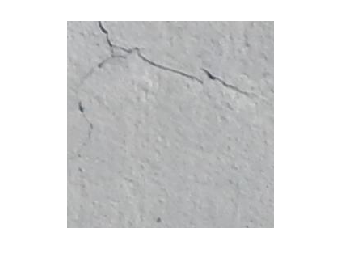

im4=imread('Crack Images\im7.jpg');
imshow(im4)

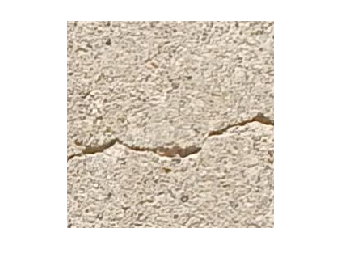

im5=imread('Crack Images\im5.jpg');
imshow(im5)

Advanced Preprocessing in MATLAB

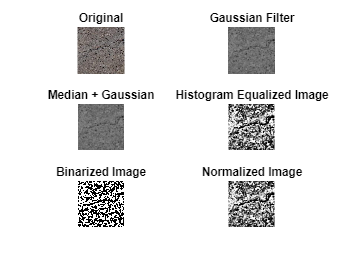

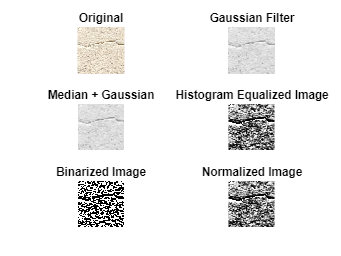

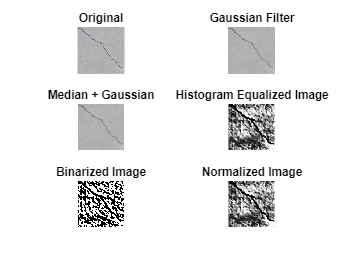

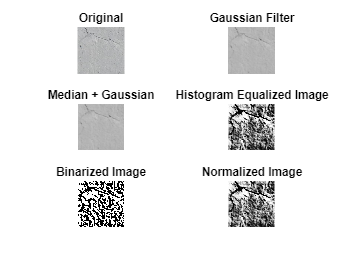

function proImg = processImage(img)
    % Grayscale conversion
    gray = rgb2gray(img);

    %Gaussian + Median Filtering
    gauss = imgaussfilt(gray, 2);
    medianFiltered = medfilt2(gauss);
    
    figure
    subplot(3,2,1), imshow(img), title('Original');
    subplot(3,2,2), imshow(gauss), title('Gaussian Filter');
    subplot(3,2,3), imshow(medianFiltered), title('Median + Gaussian');
    
    % Histogram Equalization
    equalized = histeq(medianFiltered);
    subplot(3,2,4)
    imshow(equalized); title('Histogram Equalized Image');
    
    % Adaptive Binarization
    binary = imbinarize(equalized, 'adaptive', 'Sensitivity', 0.6);
    subplot(3,2,5)
    imshow(binary); title('Binarized Image');
    
    % Normalization
    proImg = mat2gray(double(equalized));
    subplot(3,2,6)
    imshow(proImg); title('Normalized Image');
end

pro1=processImage(im1);
imwrite(pro1,'pro_im1.png')
pro2=processImage(im2);
imwrite(pro2,'pro_im2.png')
pro3=processImage(im3);
imwrite(pro3,'pro_im3.png')
pro4=processImage(im4);
imwrite(pro4,'pro_im4.png')
pro5=processImage(im5);
imwrite(pro5,'pro_im5.png')

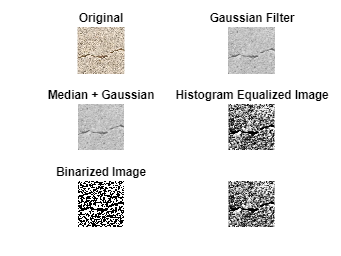


imshow(pro1)
imshow(pro2)
imshow(pro3)
imshow(pro4)
imshow(pro5)